# Ejemplo 4: calcular el volumen debajo de una superficie

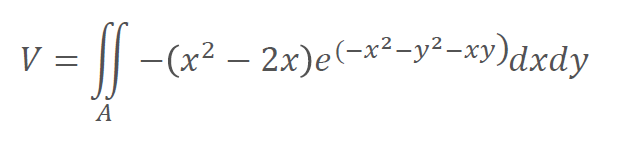


clear all; close all

% definir el dominio de integración
a=0; b=3;    % a< x <b
c=0; d=2;    % c< y <d

% definir la superficie
f=@(x,y) -(x.^2-2*x).*exp(-x.^2-y.^2-x.*y);
x = linspace(a,b,100); y = linspace(c,d,100); h = max(f(x,y));

% Definimos el volumen del hiperpoliedro R
R = (b-a)*(d-c)*h;

% Iniciar el experimento de Monte Carlo
nc=0;               % aciertos
n=5000;             % numero de intentos

% generar n números aleatorios uniformes entre 0 y 1 
r=rand(n,3);

% generamos una nube de n puntos en R [a,b]x[c,d]xh
% los puntos siguen una distribución uniforme en los intervalos
% [a,b], [c,d] y [0,h], donde h es una cota superior de f
x=a+r(:,1)*(b-a);         y=c+r(:,2)*(d-c);         z=r(:,3)*h;

% localizar los puntos que se encuentran debajo de la superficie f
idx=z<=f(x,y);
%--------------Contar el número de éxitos
nc=sum(idx);
vol_esti=R*nc/n

vol_esti = 0.3473


% Calcular el valor exacto de la integral
vol_real=integral2(f,a,b,c,d)

vol_real = 0.3538

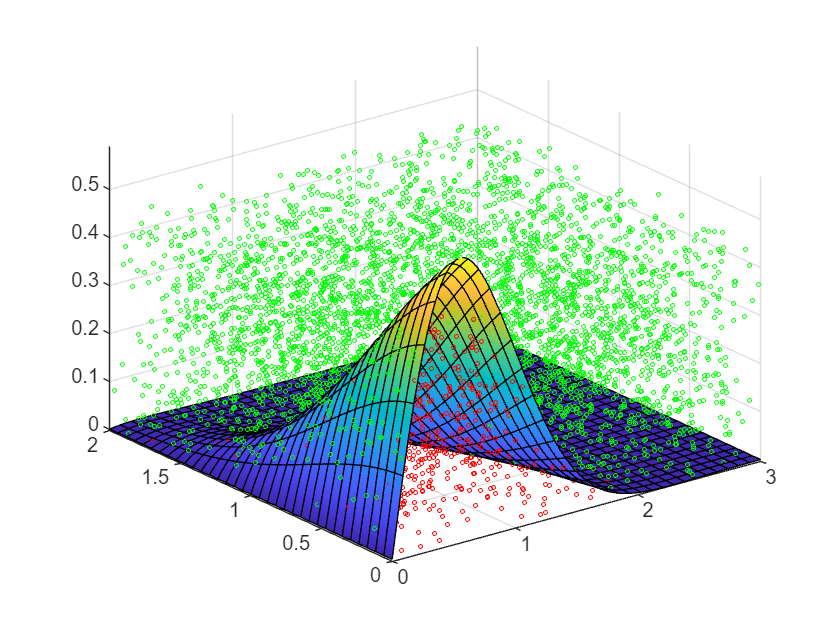


error=abs(vol_real-vol_esti);

%--------------Dibujar los resultados
fsurf(f,[0 3 0 2]);
hold on
plot3(x(idx,1),y(idx,1),z(idx,1),'ro','MarkerSize',2) % Puntos que satisfacen el criterio
plot3(x(~idx,1),y(~idx,1),z(~idx,1),'go','MarkerSize',2) % Puntos que no satisfacen el criterio